### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath(genpath('G:\My Drive\Matlab_work\Functions\GSW'))

cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')


### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9\cnv')

% Casts 
cast06 = readSBScnv( 'ar69-01_006_hyst.cnv' );
cast07 = readSBScnv( 'ar69-01_007_hyst.cnv' );
cast08 = readSBScnv( 'ar69-01_008_hyst.cnv' );
cast09 = readSBScnv( 'ar69-01_009_hyst.cnv' );
cast10 = readSBScnv( 'ar69-01_010_hyst.cnv' );
cast11 = readSBScnv( 'ar69-01_011_hyst.cnv' );
cast12 = readSBScnv( 'ar69-01_012_hyst.cnv' );
cast13 = readSBScnv( 'ar69-01_013_hyst.cnv' );
cast14 = readSBScnv( 'ar69-01_014_hyst.cnv' );
cast15 = readSBScnv( 'ar69-01_015_hyst.cnv' );
cast16 = readSBScnv( 'ar69-01_016_hyst.cnv' );
cast17 = readSBScnv( 'ar69-01_017_hyst.cnv' );
cast18 = readSBScnv( 'ar69-01_018_hyst.cnv' );
cast19 = readSBScnv( 'ar69-01_019_hyst.cnv' );
cast20 = readSBScnv( 'ar69-01_020_hyst.cnv' );
cast21 = readSBScnv( 'ar69-01_021_hyst.cnv' );
cast22 = readSBScnv( 'ar69-01_022_hyst.cnv' );
cast23 = readSBScnv( 'ar69-01_023_hyst.cnv' );


cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9\cnv')

cast06 = readSBScnv( 'ar69-01_006_nohyst.cnv' );
cast07 = readSBScnv( 'ar69-01_007_nohyst.cnv' );
cast08 = readSBScnv( 'ar69-01_008_nohyst.cnv' );
cast09 = readSBScnv( 'ar69-01_009_nohyst.cnv' );
cast10 = readSBScnv( 'ar69-01_010_nohyst.cnv' );
cast11 = readSBScnv( 'ar69-01_011_nohyst.cnv' );
cast12 = readSBScnv( 'ar69-01_012_nohyst.cnv' );
cast13 = readSBScnv( 'ar69-01_013_nohyst.cnv' );
cast14 = readSBScnv( 'ar69-01_014_nohyst.cnv' );
cast15 = readSBScnv( 'ar69-01_015_nohyst.cnv' );
cast16 = readSBScnv( 'ar69-01_016_nohyst.cnv' );
cast17 = readSBScnv( 'ar69-01_017_nohyst.cnv' );
cast18 = readSBScnv( 'ar69-01_018_nohyst.cnv' );
cast19 = readSBScnv( 'ar69-01_019_nohyst.cnv' );
cast20 = readSBScnv( 'ar69-01_020_nohyst.cnv' );
cast21 = readSBScnv( 'ar69-01_021_nohyst.cnv' );
cast22 = readSBScnv( 'ar69-01_022_nohyst.cnv' );
cast23 = readSBScnv( 'ar69-01_023_nohyst.cnv' );

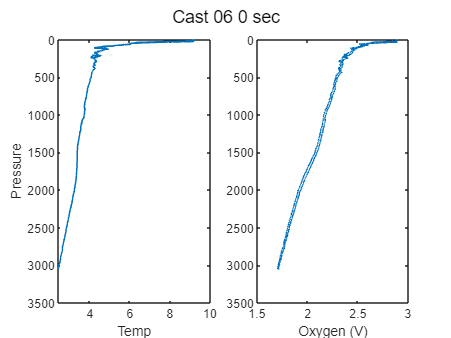

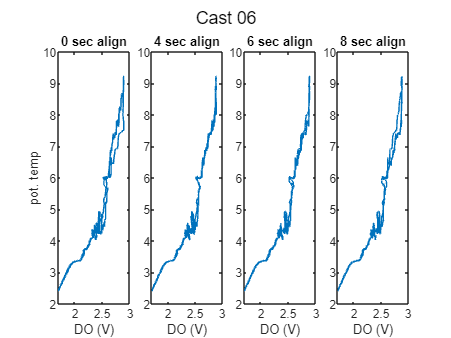

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

cast06 = align_CTD_KF(cast06,'Cast 06',a1,a2,a3);

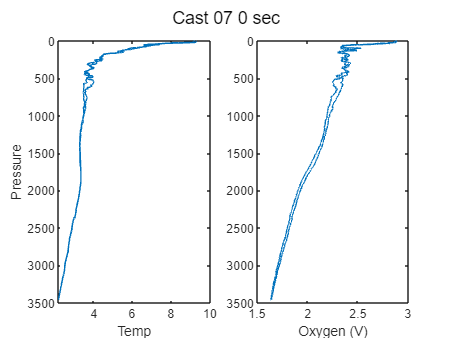

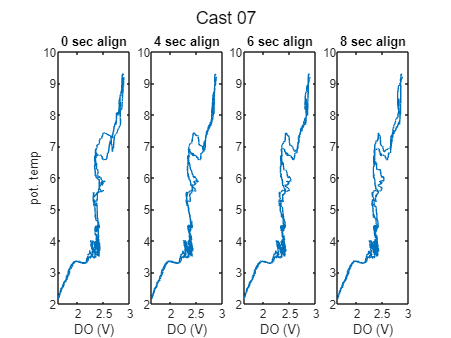

cast07 = align_CTD_KF(cast07,'Cast 07',a1,a2,a3);

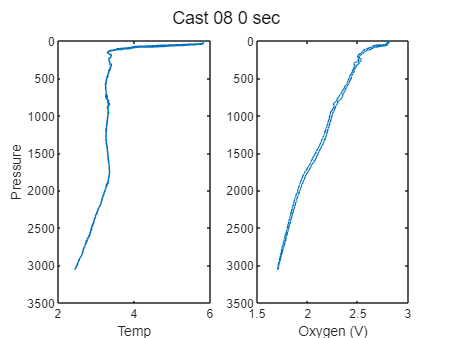

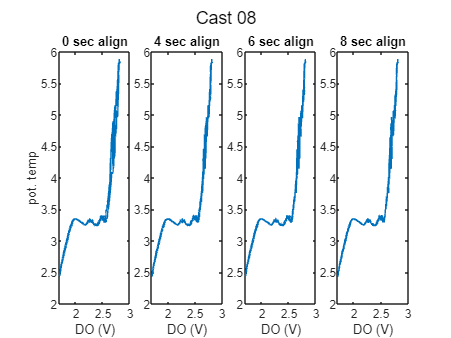

cast08 = align_CTD_KF(cast08,'Cast 08',a1,a2,a3);

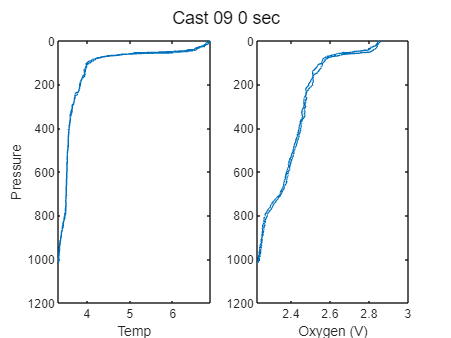

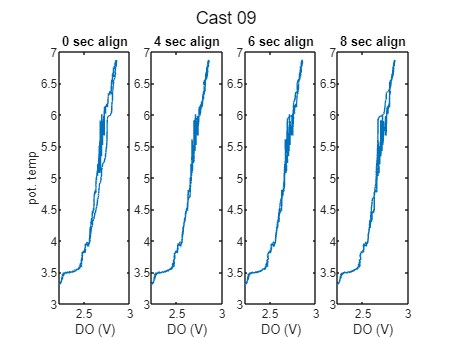

cast09 = align_CTD_KF(cast09,'Cast 09',a1,a2,a3);

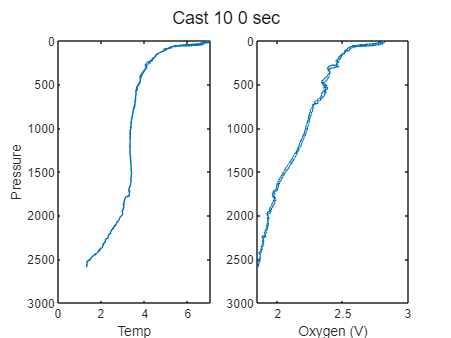

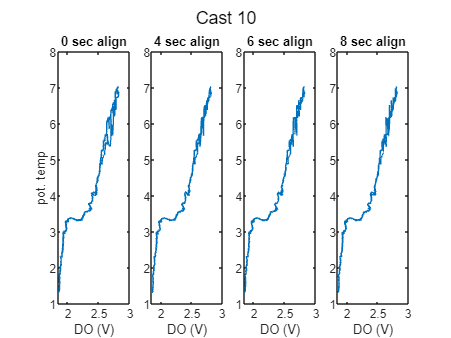

cast10 = align_CTD_KF(cast10,'Cast 10',a1,a2,a3);

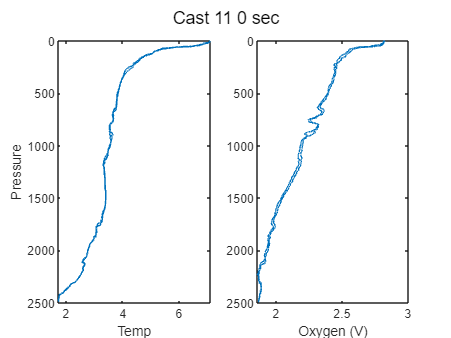

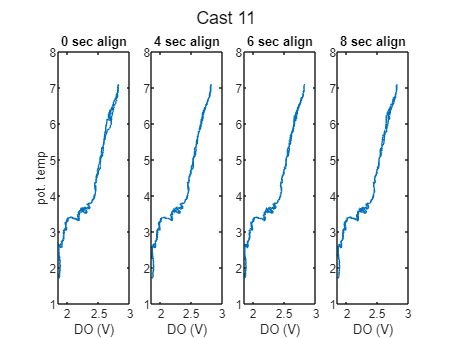

cast11 = align_CTD_KF(cast11,'Cast 11',a1,a2,a3);

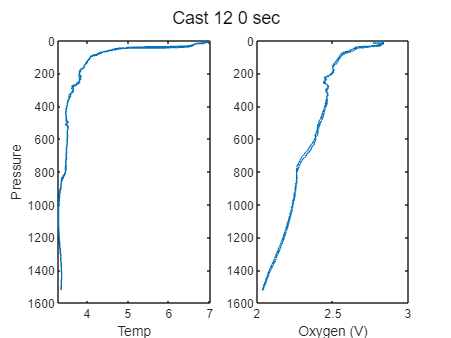

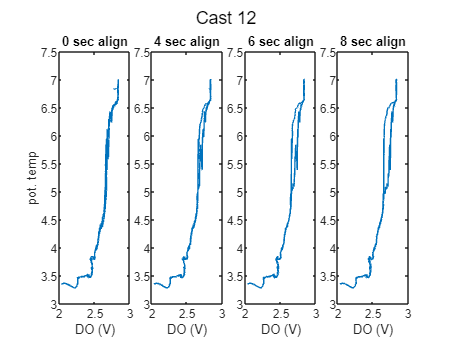

cast12 = align_CTD_KF(cast12,'Cast 12',a1,a2,a3);

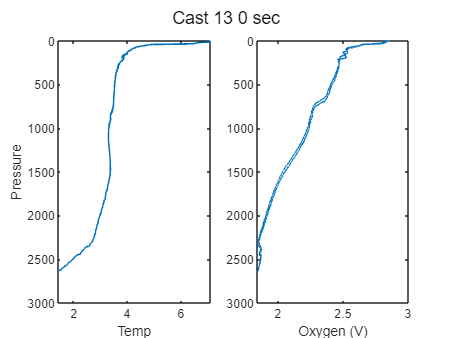

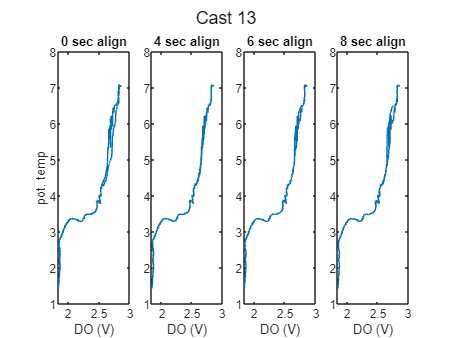

cast13 = align_CTD_KF(cast13,'Cast 13',a1,a2,a3);

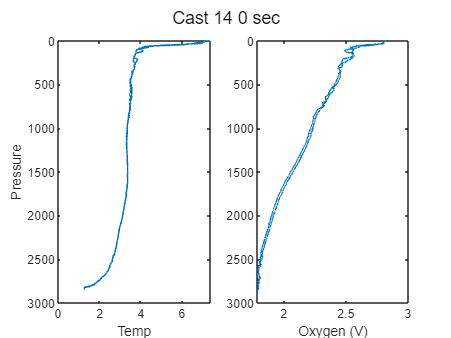

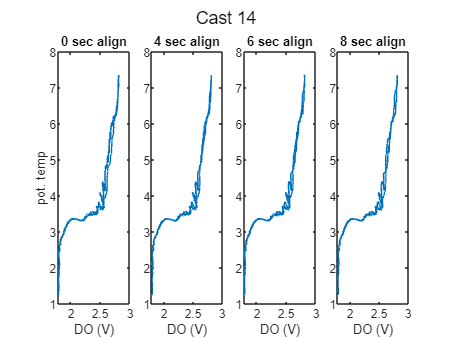

cast14 = align_CTD_KF(cast14,'Cast 14',a1,a2,a3);

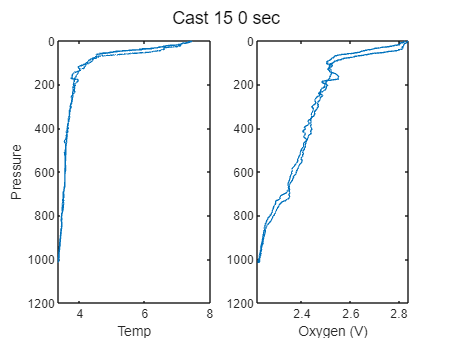

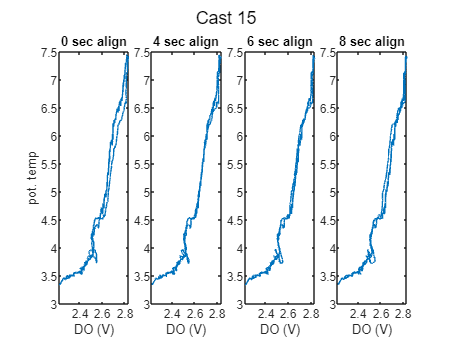

cast15 = align_CTD_KF(cast15,'Cast 15',a1,a2,a3);

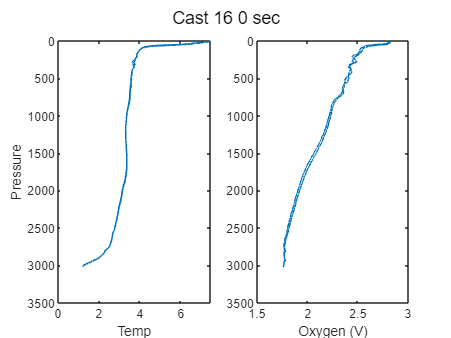

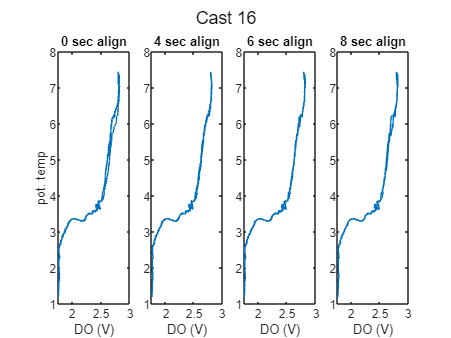

cast16 = align_CTD_KF(cast16,'Cast 16',a1,a2,a3);

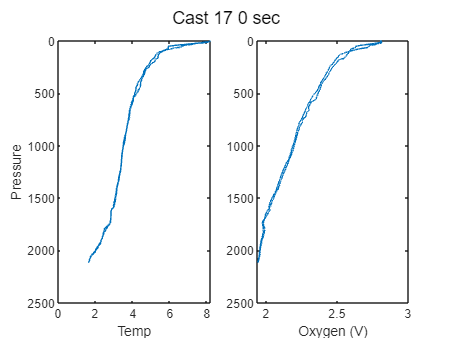

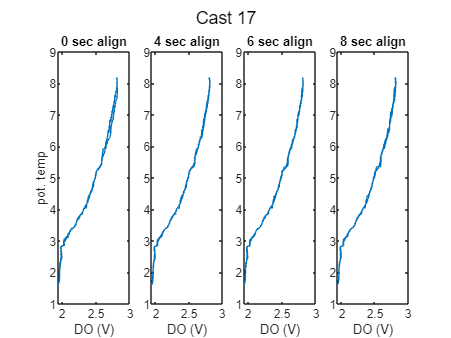

cast17 = align_CTD_KF(cast17,'Cast 17',a1,a2,a3);

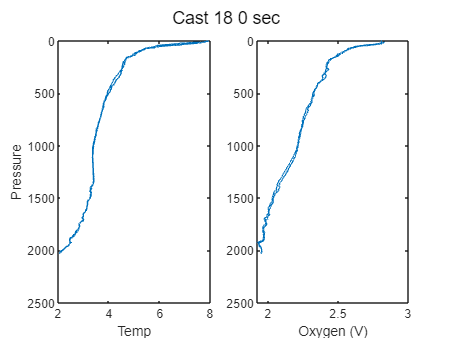

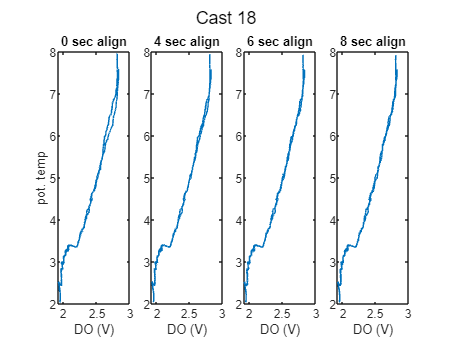

cast18 = align_CTD_KF(cast18,'Cast 18',a1,a2,a3);

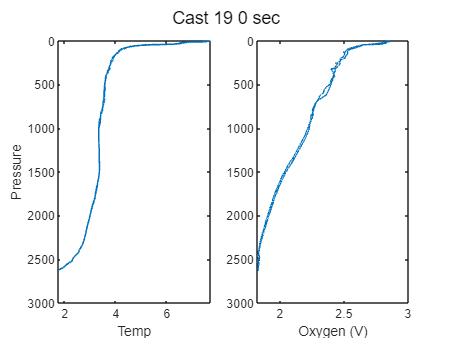

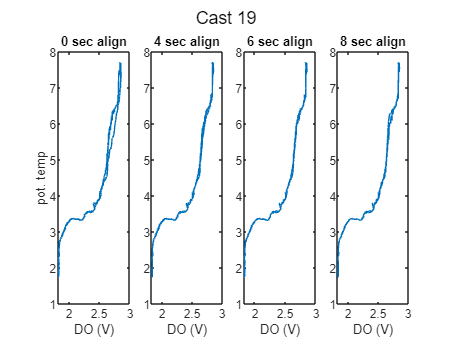

cast19 = align_CTD_KF(cast19,'Cast 19',a1,a2,a3);

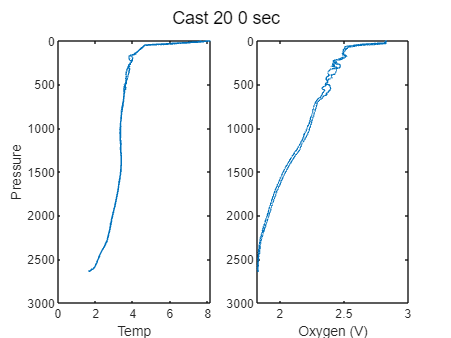

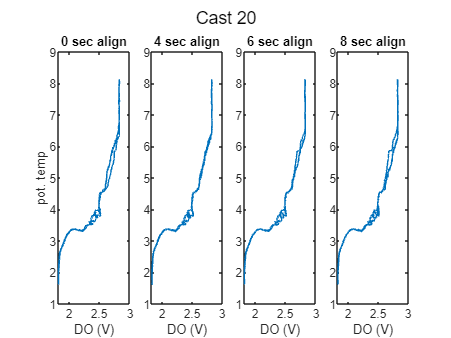

cast20 = align_CTD_KF(cast20,'Cast 20',a1,a2,a3);

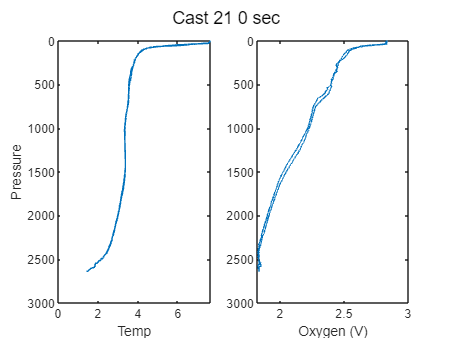

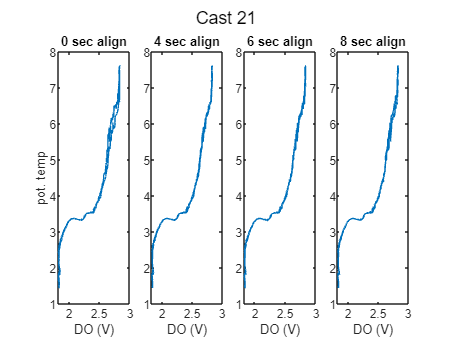

cast21 = align_CTD_KF(cast21,'Cast 21',a1,a2,a3);

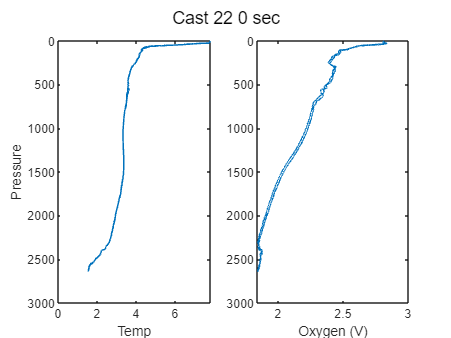

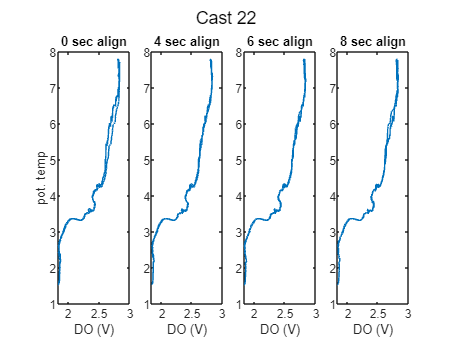

cast22 = align_CTD_KF(cast22,'Cast 22',a1,a2,a3);

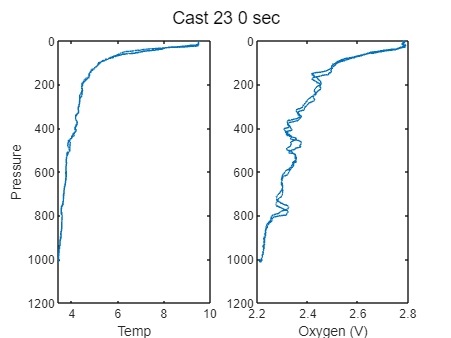

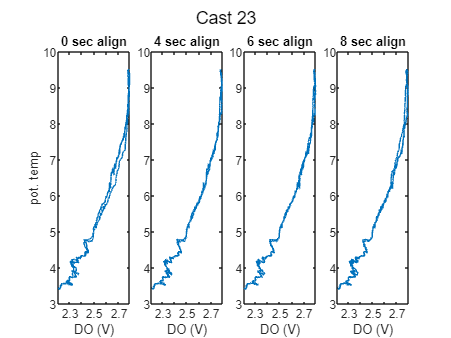

cast23 = align_CTD_KF(cast23,'Cast 23',a1,a2,a3);

% Pick align_sec

a1 = 4;
align_sec = a1; 
clear cast*

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

CTD_sen = 1; % Use primary or secondary CTD temp and sal

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year9')
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9\From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')

btl = readtable('Irminger_Sea-09_AR69-01_CTD_Sampling_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);


btlsum07 = btl(btl.Cast == 7,:);
btlsum08 = btl(btl.Cast == 8,:); % No Winklers 
% btlsum09 = btl(btl.Cast == 9,:);
btlsum10 = btl(btl.Cast == 10,:);
btlsum11 = btl(btl.Cast == 11,:);
btlsum12 = btl(btl.Cast == 12,:);
btlsum13 = btl(btl.Cast == 13,:);
btlsum14 = btl(btl.Cast == 14,:);
btlsum16 = btl(btl.Cast == 16,:); % No Winklers 
btlsum17 = btl(btl.Cast == 17,:);
btlsum18 = btl(btl.Cast == 18,:);
btlsum19 = btl(btl.Cast == 19,:);
btlsum20 = btl(btl.Cast == 20,:); % No Winklers
btlsum21 = btl(btl.Cast == 21,:);
btlsum22 = btl(btl.Cast == 22,:); % No Winklers

% [btlsum] = combine_btl_files(leah_btl_file,btl_file,btlsum,CTD_sen)
btlsum07 = combine_btl_files('ar69-01_007.cbot_s','ar69-01_007.csv',btlsum07,CTD_sen);

btlsum08 = combine_btl_files('ar69-01_008.cbot_s','ar69-01_008.csv',btlsum08,CTD_sen);

% btlsum09 =
% combine_btl_files('ar69-01_009.cbot_s','ar69-01_009.csv',btlsum09,CTD_sen);
% % missing bottle file from Leah 
btlsum10 = combine_btl_files('ar69-01_010.cbot_s','ar69-01_010.csv',btlsum10,CTD_sen);

btlsum11 = combine_btl_files('ar69-01_011.cbot_s','ar69-01_011.csv',btlsum11,CTD_sen);

btlsum12 = combine_btl_files('ar69-01_012.cbot_s','ar69-01_012.csv',btlsum12,CTD_sen);

btlsum13 = combine_btl_files('ar69-01_013.cbot_s','ar69-01_013.csv',btlsum13,CTD_sen);

btlsum14 = combine_btl_files('ar69-01_014.cbot_s','ar69-01_014.csv',btlsum14,CTD_sen);

btlsum16 = combine_btl_files('ar69-01_016.cbot_s','ar69-01_016.csv',btlsum16,CTD_sen);

btlsum17 = combine_btl_files('ar69-01_017.cbot_s','ar69-01_017.csv',btlsum17,CTD_sen);

btlsum18 = combine_btl_files('ar69-01_018.cbot_s','ar69-01_018.csv',btlsum18,CTD_sen);

btlsum19 = combine_btl_files('ar69-01_019.cbot_s','ar69-01_019.csv',btlsum19,CTD_sen);

btlsum20 = combine_btl_files('ar69-01_020.cbot_s','ar69-01_020.csv',btlsum20,CTD_sen);

btlsum21 = combine_btl_files('ar69-01_021.cbot_s','ar69-01_021.csv',btlsum21,CTD_sen);

btlsum22 = combine_btl_files('ar69-01_022.cbot_s','ar69-01_022.csv',btlsum22,CTD_sen);


btlsum0 = [btlsum07; btlsum10; btlsum11; btlsum12; btlsum13; btlsum14;...
    btlsum17; btlsum18; btlsum19; btlsum21]; % casts that are being processed for E2 and gain together 

btlsum = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12; btlsum13; btlsum14;...
    btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21; btlsum22]; 

btlsum.SA = gsw_SA_from_SP(btlsum.sal1,btlsum.prs,btlsum.lon,btlsum.lat);
btlsum.CT = gsw_CT_from_t(btlsum.SA,btlsum.t901,btlsum.prs);
btlsum.rho = gsw_rho_CT_exact(btlsum.SA,btlsum.CT,btlsum.prs); % in situ density
btlsum.prho = gsw_rho_CT_exact(btlsum.SA,btlsum.CT,0); % potential density with ref == surf
btlsum.Winkler_umolkg = btlsum.Winkler_mLL*1000*44.661./btlsum.prho; % uses potential density 

DOnohyst = btlsum.CTDoxy_mLL_nohyst*44.661.*btlsum.rho/1000;
DOhyst = btlsum.CTDoxy_mLL_hyst*44.661.*btlsum.rho/1000;
X = [btlsum.t901, btlsum.oxy_volts, datenum(btlsum.Cast), btlsum.prs];

lm0 = fitlm(X,btlsum.Winkler_umolkg)

lm0 = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)     -30.623       25.36    -1.2075       0.23026
    x1              -8.0625      1.1426    -7.0564    2.8821e-10
    x2               136.45       10.71      12.74    3.4341e-22
    x3              0.64422     0.22999     2.8011     0.0061834
    x4             0.030295    0.003038     9.9721    2.1069e-16


Number of observations: 99, Error degrees of freedom: 94
Root Mean Squared Error: 8.2
R-squared: 0.685,  Adjusted R-Squared: 0.671
F-statistic vs. constant model: 51, p-value = 9.07e-23

resid_outliers = find(isoutlier(lm0.Residuals.Raw,'median') == 1)

resid_outliers =      1
     9
    10
    28
    30
    33



% y = btlsum0.t901*0.010011 + btlsum0.CTDoxy_mLL_nohyst*1.0498 + btlsum0.Cast*0.0031966 + btlsum0.prs*0.00010029 + -0.12737;
lm = fitlm(X,btlsum.Winkler_umolkg,'Exclude',resid_outliers)

lm = Linear regression model:
    y ~ 1 + x1 + x2 + x3 + x4

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   ________    __________    _______    __________

    (Intercept)      -18.99        6.1683    -3.0786     0.0027735
    x1              -8.2711       0.27626     -29.94    6.4051e-48
    x2               135.35         2.592     52.218    5.2149e-68
    x3               0.2354      0.059933     3.9277    0.00017018
    x4             0.028993    0.00075107     38.603    6.0109e-57


Number of observations: 93, Error degrees of freedom: 88
Root Mean Squared Error: 1.97
R-squared: 0.975,  Adjusted R-Squared: 0.974
F-statistic vs. constant model: 851, p-value = 2.04e-69

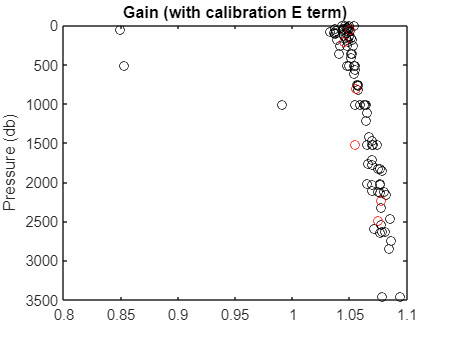

figure % Uses oxygen (ml/l) recalculated using Leah's finalized salinity product 
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_nohyst,btlsum0.PrDM,'ok')
hold on
plot(btlsum11.Winkler_mLL./btlsum11.CTDoxy_mLL_nohyst,btlsum11.PrDM,'or')
% plot(btlsum10.Winkler_mLL./btlsum10.CTDoxy_mLL_hyst,btlsum10.PrDM,'go')
% plot(btlsum21.Winkler_mLL./btlsum21.CTDoxy_mLL_hyst,btlsum21.PrDM,'ro')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

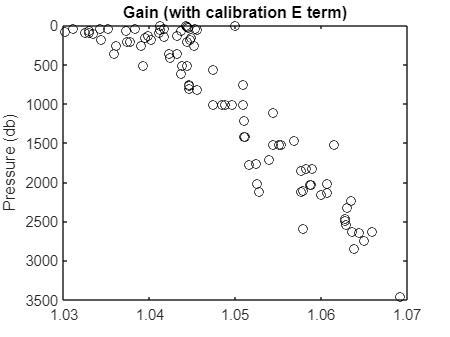


% gain0_threshold_high = 1.12;
gain0_threshold_low = 1.0;
gain0 = btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal;
Wink_bad = find(gain0 < gain0_threshold_low);
btlsum0.Winkler_mLL(Wink_bad) = NaN;

%Remove fliers 
btlsum0.Winkler_mLL(btlsum0.Cast == 7 & btlsum0.Bottle ==1) = NaN;
btlsum0.Winkler_mLL(btlsum0.Cast == 11 & btlsum0.Bottle ==5) = NaN;

figure
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL_cal,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

addpath('G:\My Drive\Matlab_work\BC')
run('GeneralSettings.m')

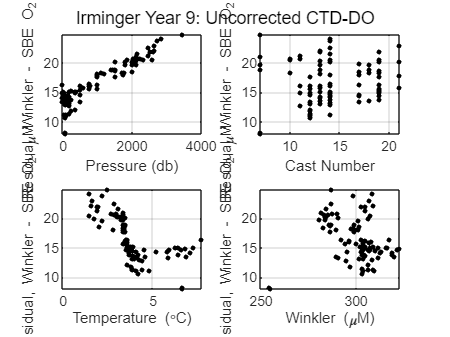

DOresid = (btlsum0.Winkler_mLL - btlsum0.CTDoxy_mLL_nohyst)*44.661;
SA = gsw_SA_from_SP(btlsum0.sal1,btlsum0.prs,btlsum0.lon,btlsum0.lat);
CT = gsw_CT_from_t(SA,btlsum0.t901,btlsum0.prs);
pt = gsw_pt_from_CT(SA,CT);

%Plot residuals versus pressure 
    figure
    subplot(2,2,1)
    plot(btlsum0.prs, DOresid, 'k.','Markersize',10); hold on;
%     plot([0 3000], 0*[0 3000], 'k--')
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Pressure (db)')
%     ylim([-10 10])
    grid on

    %Plot residuals versus cast number 
    subplot(2,2,2)
    plot(btlsum0.Cast, DOresid, 'k.','Markersize',10); hold on;
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Cast Number')
%     ylim([-10 10])
    grid on

    %Plot residuals versus temperature 
    subplot(2,2,3)
    plot(btlsum0.t901, DOresid, 'k.','Markersize',10); hold on;
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Temperature (\circC)')
%     ylim([-10 10])
    grid on

    %Plot residuals versus oxygen concentration 
    subplot(2,2,4)
    plot(btlsum0.Winkler_mLL*44.661, DOresid, 'k.','Markersize',10); hold on;
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Winkler (\muM)')
%     ylim([-10 10])
    grid on
    sgtitle(['Irminger Year 9: Uncorrected CTD-DO'])

figure
scatter(btlsum0.t901,DOresid,[],btlsum0.prs,'filled')
box on
grid on 
a = colorbar('Direction','reverse');
a.Label.String = 'Pressure (db)'
title(['Irminger Year 9: No Hysteresis Correction'])
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Temp (\circC)')

% Same Oxygen Sensor for whole cruise 
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.46780e-001);
cal.VOFFSET = double(-5.08600e-001);
cal.A = double(-5.00190e-003);
cal.B = double(2.51320e-004);
cal.C = double(-3.59380e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(1.22000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1960';
cal.OCALDATE = '31-Jul-21';

H = [-0.033, 5000, 1450]; % Default 

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing') 
[cal] = E2_calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with outlier removed

[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen); % Use dummy bottle summary with any outliers removed

### Combine Leah's processed cast files with my processed cast files 

% Read in processed casts
% Processed with 4 sec DO alignment and SBE default hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
% Casts 
cast06u = readSBScnv( 'uar69-01_006.cnv' );
cast07u = readSBScnv( 'uar69-01_007.cnv' );
cast08u = readSBScnv( 'uar69-01_008.cnv' );
cast09u = readSBScnv( 'uar69-01_009.cnv' );
cast10u = readSBScnv( 'uar69-01_010.cnv' );
cast11u = readSBScnv( 'uar69-01_011.cnv' );
cast12u = readSBScnv( 'uar69-01_012.cnv' );
cast13u = readSBScnv( 'uar69-01_013.cnv' );
cast14u = readSBScnv( 'uar69-01_014.cnv' );
cast15u = readSBScnv( 'uar69-01_015.cnv' );
cast16u = readSBScnv( 'uar69-01_016.cnv' );
cast17u = readSBScnv( 'uar69-01_017.cnv' );
cast18u = readSBScnv( 'uar69-01_018.cnv' );
cast19u = readSBScnv( 'uar69-01_019.cnv' );
cast20u = readSBScnv( 'uar69-01_020.cnv' );
cast21u = readSBScnv( 'uar69-01_021.cnv' );
cast22u = readSBScnv( 'uar69-01_022.cnv' );
cast23u = readSBScnv( 'uar69-01_023.cnv' );

cast06d = readSBScnv( 'dar69-01_006.cnv' );
cast07d = readSBScnv( 'dar69-01_007.cnv' );
cast08d = readSBScnv( 'dar69-01_008.cnv' );
cast09d = readSBScnv( 'dar69-01_009.cnv' );
cast10d = readSBScnv( 'dar69-01_010.cnv' );
cast11d = readSBScnv( 'dar69-01_011.cnv' );
cast12d = readSBScnv( 'dar69-01_012.cnv' );
cast13d = readSBScnv( 'dar69-01_013.cnv' );
cast14d = readSBScnv( 'dar69-01_014.cnv' );
cast15d = readSBScnv( 'dar69-01_015.cnv' );
cast16d = readSBScnv( 'dar69-01_016.cnv' );
cast17d = readSBScnv( 'dar69-01_017.cnv' );
cast18d = readSBScnv( 'dar69-01_018.cnv' );
cast19d = readSBScnv( 'dar69-01_019.cnv' );
cast20d = readSBScnv( 'dar69-01_020.cnv' );
cast21d = readSBScnv( 'dar69-01_021.cnv' );
cast22d = readSBScnv( 'dar69-01_022.cnv' );
cast23d = readSBScnv( 'dar69-01_023.cnv' );

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year5\Final_From_Leah')
load ar69-01_notfinal.mat

% Combine leah's finalized product with my oxygen file 
% function [cast,cast0] = combine_CTD_files(leah_cast,cast,CTD_sen)

[cast06u, cast06u0] = combine_CTD_files(ar69_006u,cast06u,CTD_sen); [cast06d, cast06d0] = combine_CTD_files(ar69_006d,cast06d,CTD_sen);  
[cast07u, cast07u0] = combine_CTD_files(ar69_007u,cast07u,CTD_sen); [cast07d, cast07d0] = combine_CTD_files(ar69_007d,cast07d,CTD_sen);  
[cast08u, cast08u0] = combine_CTD_files(ar69_008u,cast08u,CTD_sen); [cast08d, cast08d0] = combine_CTD_files(ar69_008d,cast08d,CTD_sen);  
[cast09u, cast09u0] = combine_CTD_files(ar69_009u,cast09u,CTD_sen); [cast09d, cast09d0] = combine_CTD_files(ar69_009d,cast09d,CTD_sen);  
[cast10u, cast10u0] = combine_CTD_files(ar69_010u,cast10u,CTD_sen); [cast10d, cast10d0] = combine_CTD_files(ar69_010d,cast10d,CTD_sen);  
[cast11u, cast11u0] = combine_CTD_files(ar69_011u,cast11u,CTD_sen); [cast11d, cast11d0] = combine_CTD_files(ar69_011d,cast11d,CTD_sen);  
[cast12u, cast12u0] = combine_CTD_files(ar69_012u,cast12u,CTD_sen); [cast12d, cast12d0] = combine_CTD_files(ar69_012d,cast12d,CTD_sen);  
[cast13u, cast13u0] = combine_CTD_files(ar69_013u,cast13u,CTD_sen); [cast13d, cast13d0] = combine_CTD_files(ar69_013d,cast13d,CTD_sen);  
[cast14u, cast14u0] = combine_CTD_files(ar69_014u,cast14u,CTD_sen); [cast14d, cast14d0] = combine_CTD_files(ar69_014d,cast14d,CTD_sen);  
[cast15u, cast15u0] = combine_CTD_files(ar69_015u,cast15u,CTD_sen); [cast15d, cast15d0] = combine_CTD_files(ar69_015d,cast15d,CTD_sen);  
[cast16u, cast16u0] = combine_CTD_files(ar69_016u,cast16u,CTD_sen); [cast16d, cast16d0] = combine_CTD_files(ar69_016d,cast16d,CTD_sen);  
[cast17u, cast17u0] = combine_CTD_files(ar69_017u,cast17u,CTD_sen); [cast17d, cast17d0] = combine_CTD_files(ar69_017d,cast17d,CTD_sen);  
[cast18u, cast18u0] = combine_CTD_files(ar69_018u,cast18u,CTD_sen); [cast18d, cast18d0] = combine_CTD_files(ar69_018d,cast18d,CTD_sen);  
[cast19u, cast19u0] = combine_CTD_files(ar69_019u,cast19u,CTD_sen); [cast19d, cast19d0] = combine_CTD_files(ar69_019d,cast19d,CTD_sen);  
[cast20u, cast20u0] = combine_CTD_files(ar69_020u,cast20u,CTD_sen); [cast20d, cast20d0] = combine_CTD_files(ar69_020d,cast20d,CTD_sen);  
[cast21u, cast21u0] = combine_CTD_files(ar69_021u,cast21u,CTD_sen); [cast21d, cast21d0] = combine_CTD_files(ar69_021d,cast21d,CTD_sen);  
[cast22u, cast22u0] = combine_CTD_files(ar69_022u,cast22u,CTD_sen); [cast22d, cast22d0] = combine_CTD_files(ar69_022d,cast22d,CTD_sen);  
[cast23u, cast23u0] = combine_CTD_files(ar69_023u,cast23u,CTD_sen); [cast23d, cast23d0] = combine_CTD_files(ar69_023d,cast23d,CTD_sen);  

### Correct casts using new SOC term, E term, and Leah's calibrated salinity product

sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_v2(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_v2(cast06u,cast06d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 06');
[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_v2(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen,'Cast 07');
[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_v2(cast08u,cast08d,cal,btlsum08,sal_plots,leah_plot,CTD_sen,'Cast 08');
[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_v2(cast09u,cast09d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 09');
[cast10u, cast10d, btlsum10] = Process_Cast_Gain_E2_v2(cast10u,cast10d,cal,btlsum10,sal_plots,leah_plot,CTD_sen,'Cast 10'); 
[cast11u, cast11d, btlsum11] = Process_Cast_Gain_E2_v2(cast11u,cast11d,cal,btlsum11,sal_plots,leah_plot,CTD_sen,'Cast 11');
[cast12u, cast12d, btlsum12] = Process_Cast_Gain_E2_v2(cast12u,cast12d,cal,btlsum12,sal_plots,leah_plot,CTD_sen,'Cast 12');
[cast13u, cast13d, btlsum13] = Process_Cast_Gain_E2_v2(cast13u,cast13d,cal,btlsum13,sal_plots,leah_plot,CTD_sen,'Cast 13');
[cast14u, cast14d, btlsum14] = Process_Cast_Gain_E2_v2(cast14u,cast14d,cal,btlsum14,sal_plots,leah_plot,CTD_sen,'Cast 14');
[cast15u, cast15d, btlsum15] = Process_Cast_Gain_E2_v2(cast15u,cast15d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 15');
[cast16u, cast16d, btlsum16] = Process_Cast_Gain_E2_v2(cast16u,cast16d,cal,btlsum16,sal_plots,leah_plot,CTD_sen,'Cast 16');
[cast17u, cast17d, btlsum17] = Process_Cast_Gain_E2_v2(cast17u,cast17d,cal,btlsum17,sal_plots,leah_plot,CTD_sen,'Cast 17');
[cast18u, cast18d, btlsum18] = Process_Cast_Gain_E2_v2(cast18u,cast18d,cal,btlsum18,sal_plots,leah_plot,CTD_sen,'Cast 18');
[cast19u, cast19d, btlsum19] = Process_Cast_Gain_E2_v2(cast19u,cast19d,cal,btlsum19,sal_plots,leah_plot,CTD_sen,'Cast 19');
[cast20u, cast20d, btlsum20] = Process_Cast_Gain_E2_v2(cast20u,cast20d,cal,btlsum20,sal_plots,leah_plot,CTD_sen,'Cast 20');
[cast21u, cast21d, btlsum21] = Process_Cast_Gain_E2_v2(cast21u,cast21d,cal,btlsum21,sal_plots,leah_plot,CTD_sen,'Cast 21'); 
[cast22u, cast22d, btlsum22] = Process_Cast_Gain_E2_v2(cast22u,cast22d,cal,btlsum22,sal_plots,leah_plot,CTD_sen,'Cast 22');
[cast23u, cast23d, btlsum23] = Process_Cast_Gain_E2_v2(cast23u,cast23d,cal,0,sal_plots,leah_plot,CTD_sen,'Cast 23');


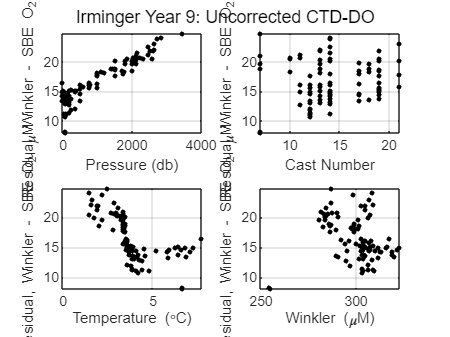

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
load Year9_Processed_KF.mat 
% btlsum_yr9 = [btlsum07; btlsum08; btlsum10; btlsum11; btlsum12; btlsum13; btlsum14;...
%     btlsum16; btlsum17; btlsum18; btlsum19; btlsum20; btlsum21; btlsum22]; 

X = [btlsum0.t901, btlsum0.CTDoxy_mLL_nohyst, datenum(btlsum0.Date), btlsum0.prs];

lm = fitlm(X,btlsum0.Winkler_mLL);
y = btlsum0.t901*0.010011 + btlsum0.CTDoxy_mLL_nohyst*1.0498 + btlsum0.Cast*0.0031966 + btlsum0.prs*0.00010029 + -0.12737;

lmresid = (btlsum0.Winkler_mLL - y)*44.661;
%myresid = (btlsum0.Winkler_mLL -btlsum0. - btlsum_yr9.DOcorr_mLL)*44.661,'*','Color',red)
grid on

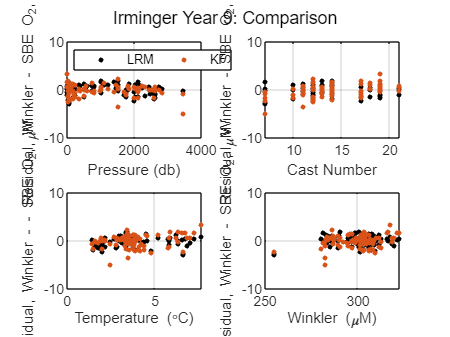


%Plot residuals versus pressure 
    figure
    subplot(2,2,1)
    plot(btlsum0.prs, lmresid,'.k','Markersize',10)
    hold on
    plot(btlsum_yr9.prs, (btlsum_yr9.Winkler_mLL-btlsum_yr9.DOcorr_mLL)*44.661,'.','Markersize',10 )
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Pressure (db)')
     ylim([-10 10])
    grid on
    legend('LRM','KF','Location','NW','Orientation','Horizontal')

    %Plot residuals versus cast number 
    subplot(2,2,2)
    plot(btlsum0.Cast, lmresid, 'k.','Markersize',10); hold on;
    plot(btlsum_yr9.Cast, (btlsum_yr9.Winkler_mLL-btlsum_yr9.DOcorr_mLL)*44.661,'.','Markersize',10 )
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Cast Number')
     ylim([-10 10])
    grid on

    %Plot residuals versus temperature 
    subplot(2,2,3)
    plot(btlsum0.t901, lmresid, 'k.','Markersize',10); hold on;
    plot(btlsum_yr9.t, (btlsum_yr9.Winkler_mLL-btlsum_yr9.DOcorr_mLL)*44.661,'.','Markersize',10 )
    ylabel('Residual, Winkler - - SBE O_2, \muM')
    xlabel('Temperature (\circC)')
     ylim([-10 10])
    grid on

    %Plot residuals versus oxygen concentration 
    subplot(2,2,4)
    plot(btlsum0.Winkler_mLL*44.661, lmresid, 'k.','Markersize',10); hold on;
    plot(btlsum_yr9.Winkler_mLL*44.661, (btlsum_yr9.Winkler_mLL-btlsum_yr9.DOcorr_mLL)*44.661,'.','Markersize',10 )
    ylabel('Residual, Winkler - SBE O_2, \muM')
    xlabel('Winkler (\muM)')
     ylim([-10 10])
    grid on
    sgtitle(['Irminger Year 9: Comparison'])


btlsum_yr9_OOI = [btlsum12; btlsum13; btlsum14; btlsum19; btlsum20; btlsum21; btlsum22];

oxy_diff = btlsum_yr9.Winkler_umolkg-btlsum_yr9.DOcorr_umolkg;

figure
plot(oxy_diff,btlsum_yr9.prs,'ok')
axis ij
grid on
ylabel('Depth (db)')
xlabel('Winkler - CTD corrected (\mumol kg^-^1)')
title('Oxygen differences vs depth')

% nanmean(abs(oxy_diff(oxy_diff <10)))
% nanstd(abs(oxy_diff(oxy_diff <10)))



disp(['DO align (s) = ' num2str(align_sec)])
disp(['Cal. E term = ' num2str(cal.E)])
disp(['Adjust. E term (E2) = ' num2str(cal.E2)])
disp(['Cal SOC = ' num2str(cal.SOC)])
disp(['New SOC = ' num2str(cal.SOCnew) ])
disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])


run('Year9_PT_DO_plots.m')

% cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year9')
% clear btlsum0 btl
% dt_Processed = datetime;
% save Year9_Processed_KF cast* btl* cal* dt_Processed 